% Author: Fazal Mahmud Niloy
% Date created: 30/04/2023

close all;
clear variables;
clc;

## Read the training, validation and test partitions from the relevant

folder = "CUB_200_2011_Subset20Classes";
trainingImageNames = readtable(fullfile(folder, "train.txt"),'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(fullfile(folder, "validate.txt"),'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(fullfile(folder, "test.txt"),'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(fullfile(folder, "classes.txt"),'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(fullfile(folder, "image_class_labels.txt"),'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

folder = "CUB_200_2011_Subset20Classes/";
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;

validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;

testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;

## The images all have different spatial resolutions (width x height), so

targetSize = [224, 224];
trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

% taking the first image as the sample image
sample_img = cdsTraining.read{1};

cellSize = [32 32]; 

[hog_8x8, vis8x8] = extractHOGFeatures(sample_img,'CellSize',cellSize);
numImagesTrain = numel(trainingImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
hogFeatureSize = length(hog_8x8);
[hog_8x8, vis8x8] = extractHOGFeatures(sample_img,'CellSize',cellSize);

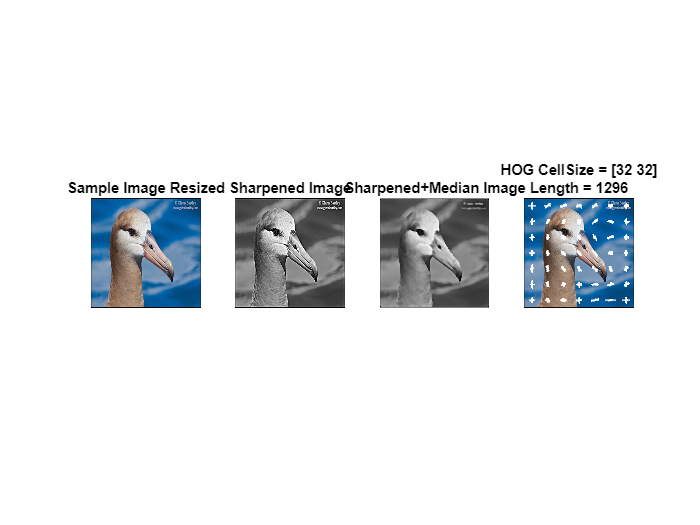

% testing on one image
subplot(1, 4, 1);
imshow(sample_img);
title('Sample Image Resized');

subplot(1, 4, 2);
imshow(rgb2gray(sample_img)); hold on;
% sharpening and adding median filter
J = imsharpen(im2gray(sample_img),"Radius",2,"Amount",1);
imshow(J);
title('Sharpened Image');

subplot(1, 4, 3);
imshow(rgb2gray(sample_img)); hold on;
% sharpening and adding median filter
J = imsharpen(im2gray(sample_img),"Radius",2,"Amount",1);
K = medfilt2(J,[5 5]);
imshow(K);
title('Sharpened+Median Image');

subplot(1, 4, 4);
imshow(sample_img); hold on;
plot(vis8x8); 
title({'HOG CellSize = [32 32]'; ['Length = ' num2str(hogFeatureSize)]});

## Extract HOG features

% HOG
trainImagesCount = numel(trainingImageDS_Resized.UnderlyingDatastores{1, 1}.Files);

% separating features in different datastructures
trainingFeaturesHOG = zeros(trainImagesCount, hogFeatureSize, 'single');
sharpenedHOGFeatures = zeros(trainImagesCount, hogFeatureSize, 'single');
medianSharpenedHOGFeatures = zeros(trainImagesCount, hogFeatureSize, 'single');

reset(cdsTraining);
for i = 1:trainImagesCount
    imgFromDS = read(cdsTraining); 
    imgGray = im2gray(imgFromDS{1});

    % sharpening and adding median filter
    img_sharpened = imsharpen(im2gray(sample_img),"Radius",2,"Amount",1);
    img_median = medfilt2(img_sharpened,[5 5]);

    trainingFeaturesHOG(i,:) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
    sharpenedHOGFeatures(i, :) = extractHOGFeatures(img_median, 'CellSize', cellSize);
    medianSharpenedHOGFeatures(i, :) = extractHOGFeatures(img_median, 'CellSize', cellSize);
end

% combine base image feature and reduced noise feature
trainingFeaturesHOG = [trainingFeaturesHOG sharpenedHOGFeatures medianSharpenedHOGFeatures];

% HOG test
testImagesCount = numel(testImageDS_Resized.UnderlyingDatastores{1, 1}.Files);

testFeaturesHOG = zeros(testImagesCount, hogFeatureSize, 'single');
testSharpenedHOGFeatures = zeros(testImagesCount, hogFeatureSize, 'single');
testMedianSharpenedHOGFeatures = zeros(testImagesCount, hogFeatureSize, 'single');

reset(cdsTest);     % Make sure we start with the first image

for i = 1:testImagesCount
    imgFromDS = read(cdsTest);    % Get item from datastore
    imgGray = im2gray(imgFromDS{1});  % Ensure images are grayscale

    img_sharpened = imsharpen(im2gray(sample_img),"Radius",2,"Amount",1);
    img_median = medfilt2(img_sharpened,[5 5]);

    testFeaturesHOG(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
    testSharpenedHOGFeatures(i, :) = extractHOGFeatures(img_sharpened, 'CellSize', cellSize);
    testMedianSharpenedHOGFeatures(i, :) = extractHOGFeatures(img_median, 'CellSize', cellSize);
end

% combine test features
testFeaturesHOG = [testFeaturesHOG testSharpenedHOGFeatures testMedianSharpenedHOGFeatures];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              true      



## Train a multi-class SVM

Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       7 | Best   |     0.85886 |      28.409 |     0.85886 |     0.86257 |   9.7197e-07 |
|    2 |       7 | Accept |     0.87387 |      28.427 |     0.85886 |     0.86257 |   9.0755e-05 |
|    3 |       2 | Best   |     0.84985 |      29.219 |     0.84985 |     0.86524 |    0.0078812 |
|    4 |       2 | Accept |     0.88138 |      28.876 |     0.84985 |     0.86524 |      0.74137 |
|    5 |       2 | Accept |     0.86186 |      28.768 |     0.84985 |     0.86524 |   0.00017785 |
|    6 |       2 | Accep

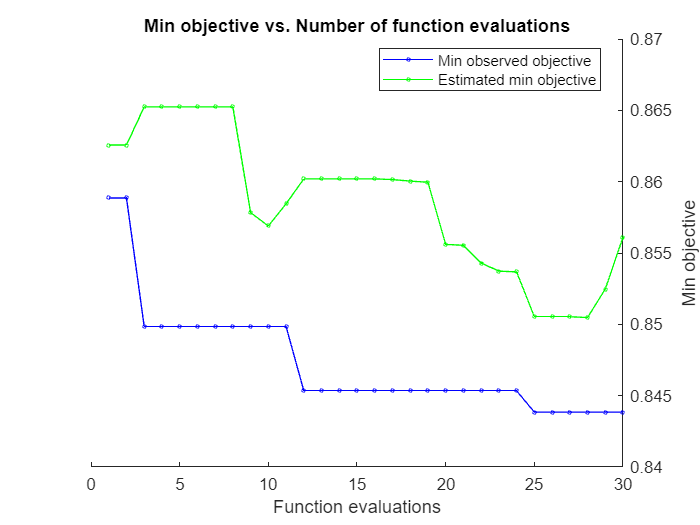

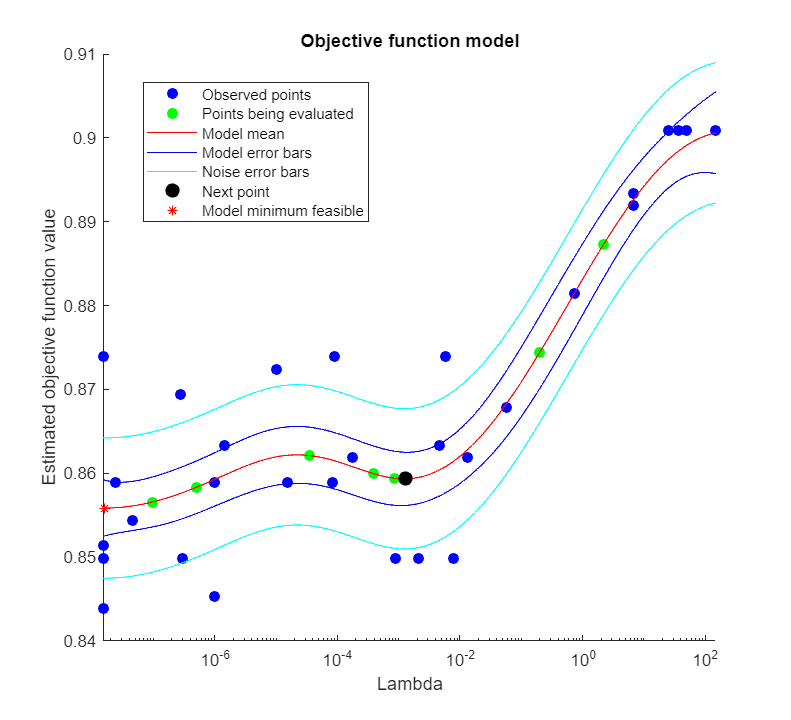


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 108.8173 seconds
Total objective function evaluation time: 785.4367

Best observed feasible point:
      Lambda  
    __________

    1.5052e-08

Observed objective function value = 0.84384
Estimated objective function value = 0.85585
Function evaluation time = 27.1147

Best estimated feasible point (according to models):
     Lambda  
    _________

    4.585e-08

Estimated objective function value = 0.85611
Estimated function evaluation time = 27.343



t = templateLinear('Solver', 'dual');
options = struct('UseParallel', true);

% fitcecoc uses multiple SVM learners and a 'One-vs-One' encoding scheme.
Classifier = fitcecoc(trainingFeaturesHOG, trainingImageDS.Labels, 'Learners', t,...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);

## Test the accuracy on the test partition

YPred = predict(Classifier, testFeaturesHOG);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest); 
accuracy

accuracy = 0.1486

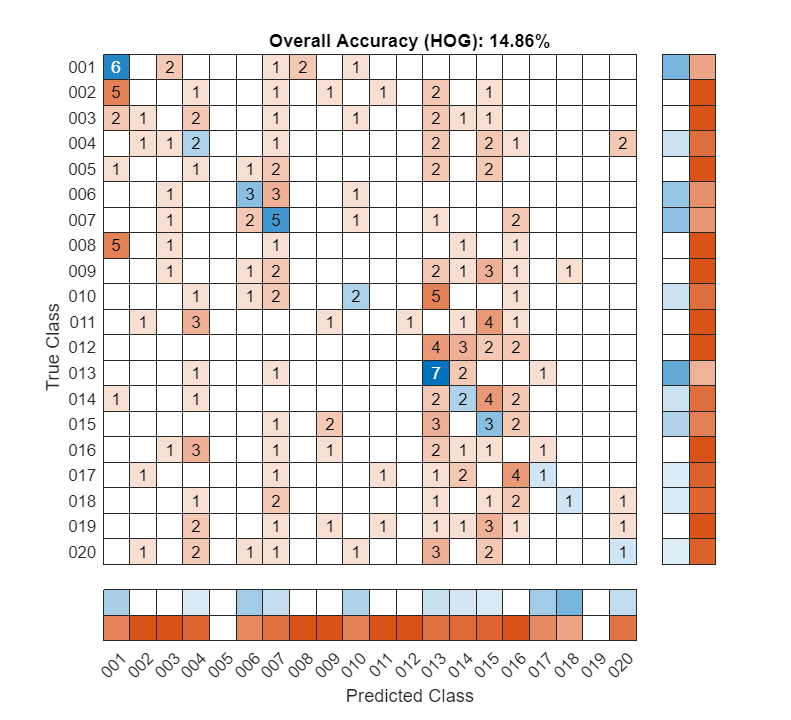


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (HOG): "+ string(round(accuracy*100, 2)) +"%");